% Boedo and Prantil 1998: corrected solution of clamped ring plate with edge point load
% https://ascelibrary.org/doi/epdf/10.1061/%28ASCE%290733-9399%281998%29124%3A6%28696%29

## Comparison against Boedo paper

%clear
N = 100;

lam = 2/3;
nu = 0.3;

theta = 0:pi/8:pi;
rho = 2/3;
[~,Mr_nondim,abcd] = concentrated_plate_nondim(lam,nu,theta,rho,N);

format shortE
abcd(1:10,:)

ans =   -2.4628e-01   2.6060e-01  -2.1064e-01  -2.5000e-01
   5.6862e-02  -1.1715e-01   8.7971e-02   5.0000e-01
   1.4973e-01  -3.6700e-02   2.3133e-02  -1.1135e-01
   5.9034e-02  -1.8376e-02   8.2143e-03  -2.8530e-02
   3.3377e-02  -1.1777e-02   3.0900e-03  -9.4233e-03
   2.1425e-02  -8.5354e-03   1.1572e-03  -3.2917e-03
   1.4625e-02  -6.5209e-03   4.2958e-04  -1.1699e-03
   1.0416e-02  -5.1113e-03   1.5962e-04  -4.2191e-04
   7.6881e-03  -4.0805e-03   5.9845e-05  -1.5477e-04
   5.8546e-03  -3.3123e-03   2.2727e-05  -5.7808e-05


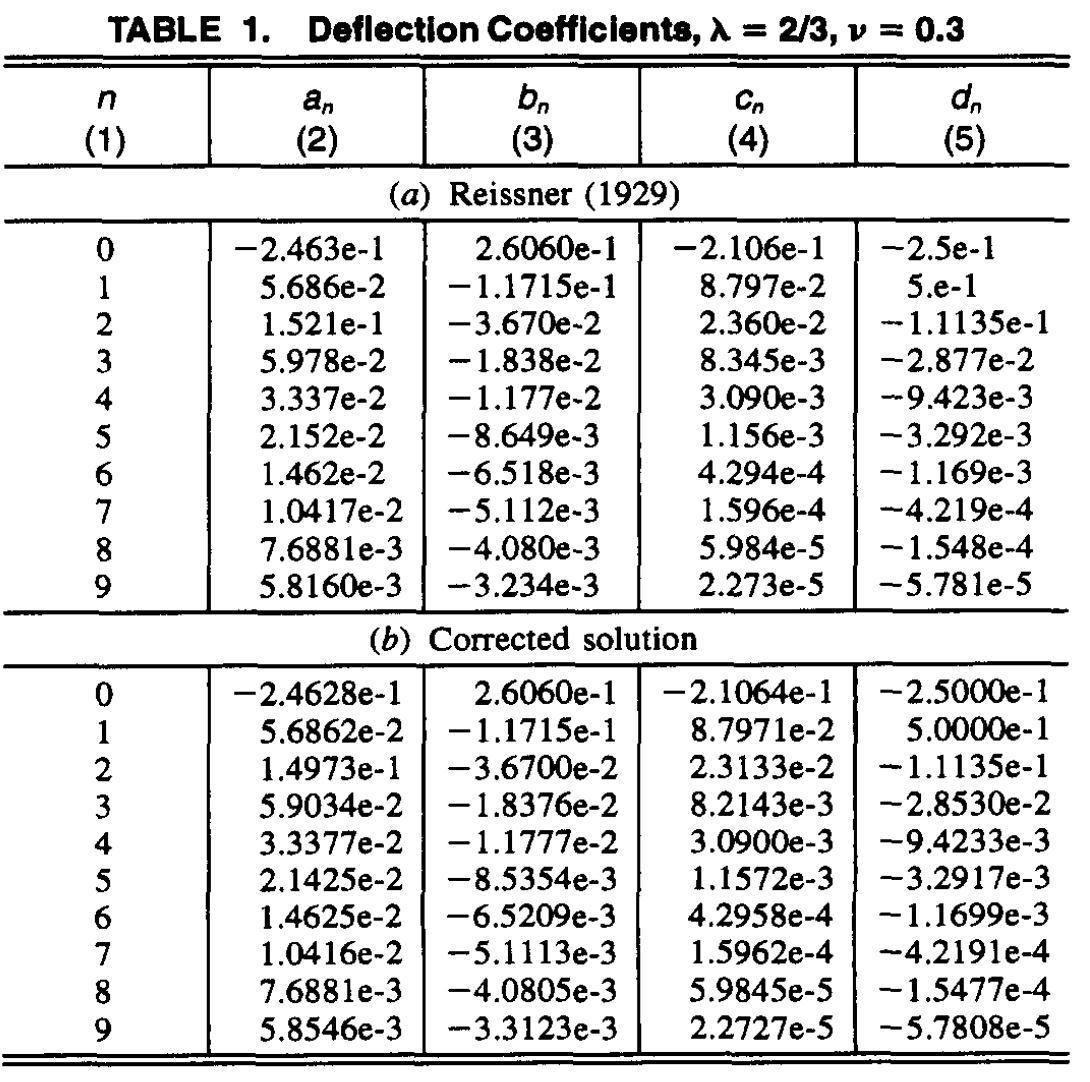

Mr_nondim'

ans =   -4.4222e+00
  -1.4283e+00
  -2.3439e-02
   4.5735e-02
   8.4898e-03
  -7.6379e-05
  -2.9049e-04
  -4.4280e-05
   3.6329e-06


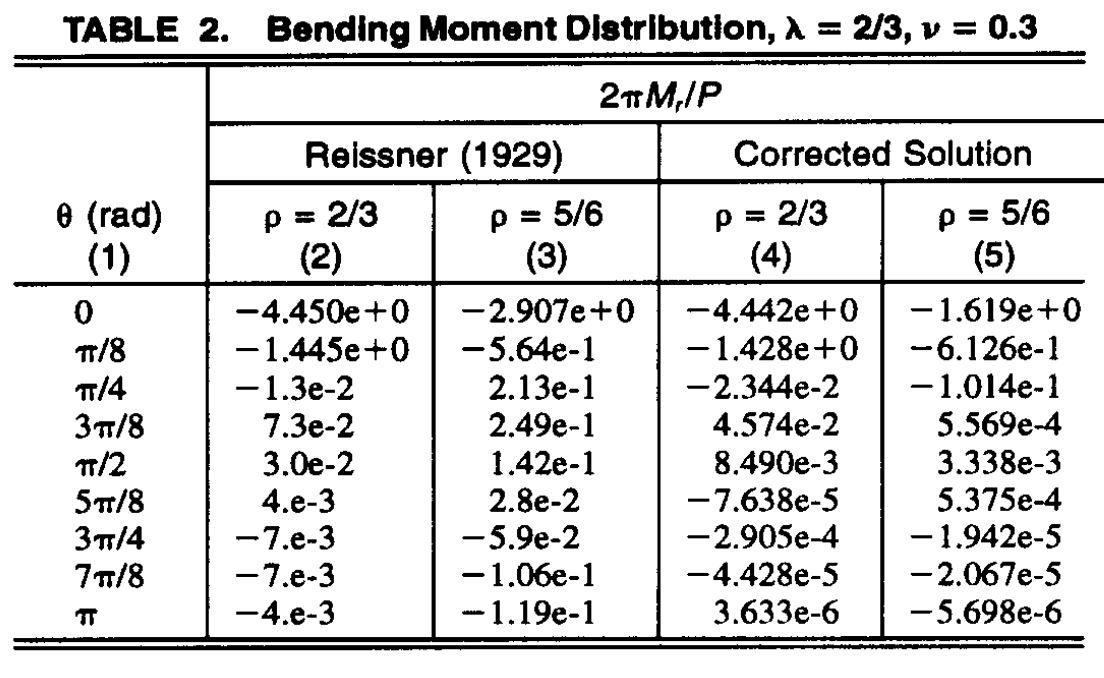

sigma_nondim = 3/pi * abs(Mr_nondim(1))

sigma_nondim =    4.2229e+00


format default

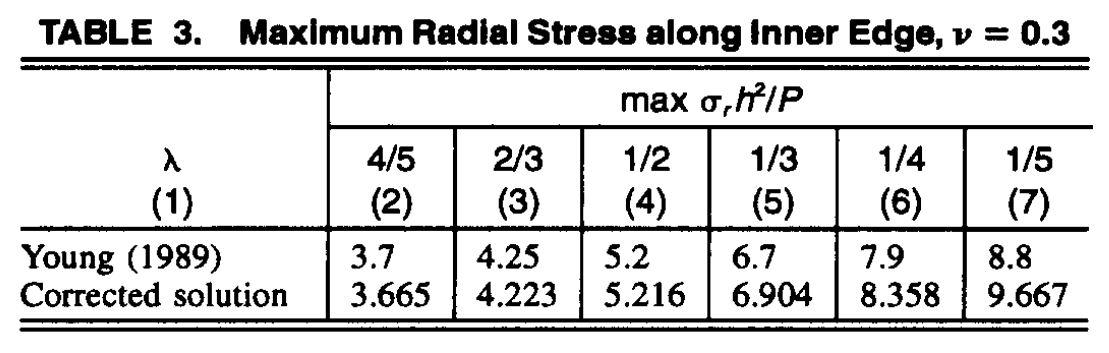

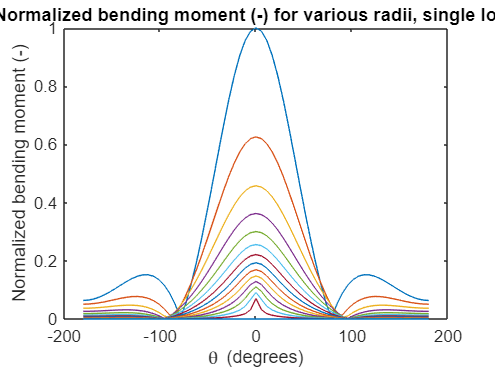

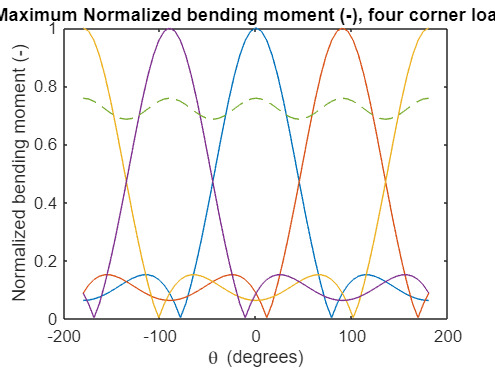

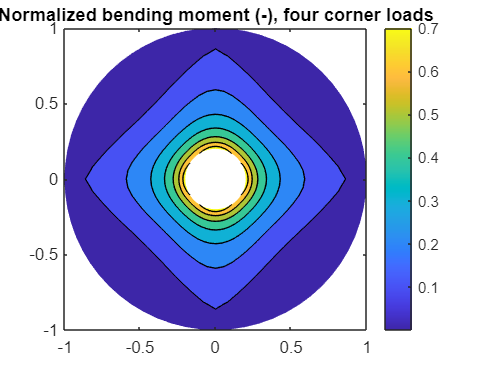

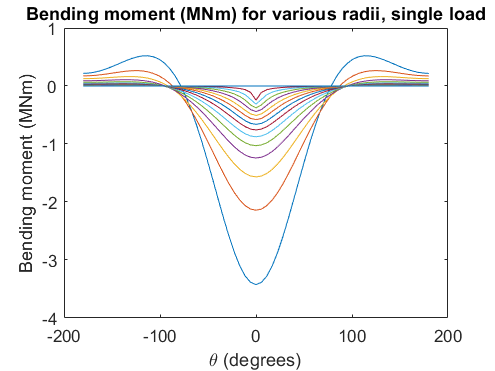

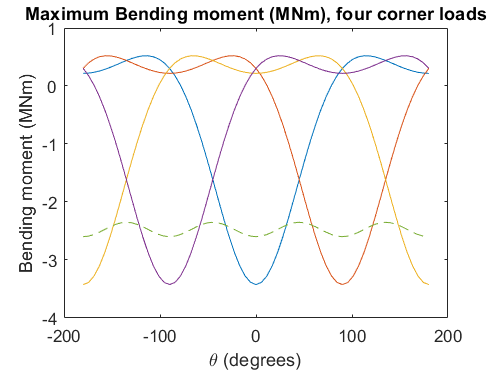

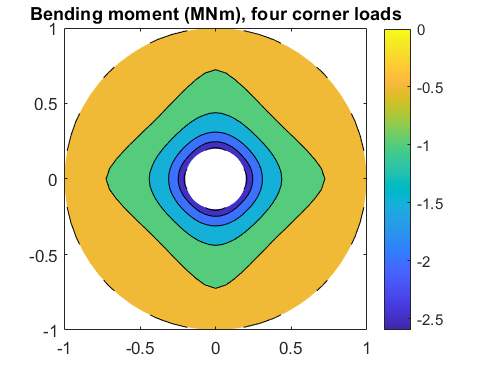

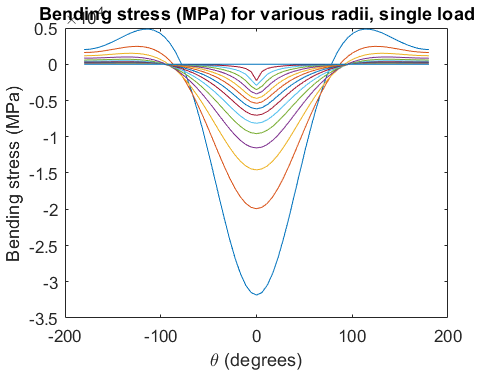

w_nondim =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0119    0.0118    0.0114    0.0107    0.0098    0.0088    0.0076    0.0063    0.0050    0.0037    0.0025    0.0014    0.0003   -0.0006   -0.0014   -0.0021   -0.0026   -0.0030   -0.0033   -0.0035   -0.0036   -0.0037   -0.0036   -0.0036   -0.0034   -0.0033   -0.0032   -0.0030   -0.0029   -0.0028   -0.0027   -0.0027   -0.0027
    0.0414    0.0409    0.0395    0.0372    0.0342    0.0306    0.0265    0.0222    0.0178    0.0134    0.0092    0.0052    0.0016   -0.0015   -0.0043   -0.0066   -0.0085   -0.0100   -0.0111   -0.0118   -0.0122   -0.0124   -0.0123   -0.0121   -0.0118   -0.0114   -0.0110   -0.0106   -0.0102   -0.0099   -0.0097   -0.0095   -0.0

Mr_nondim =   -11.3499  -11.2402  -10.9170  -10.3980   -9.7102   -8.8880   -7.9698   -6.9950   -6.0016   -5.0238   -4.0908   -3.2258   -2.4460   -1.7626   -1.1817   -0.7045   -0.3283   -0.0473    0.1465    0.2630    0.3129    0.3077    0.2586    0.1769    0.0733   -0.0425   -0.1615   -0.2758   -0.3787   -0.4645   -0.5290   -0.5689   -0.5824
   -7.1719   -7.1122   -6.9360   -6.6522   -6.2746   -5.8205   -5.3094   -4.7616   -4.1968   -3.6330   -3.0861   -2.5692   -2.0925   -1.6635   -1.2867   -0.9644   -0.6966   -0.4815   -0.3160   -0.1958   -0.1156   -0.0700   -0.0529   -0.0586   -0.0812   -0.1152   -0.1556   -0.1978   -0.2379   -0.2726   -0.2993   -0.3160   -0.3217
   -5.2336   -5.1892   -5.0589   -4.8502   -4.5748   -4.2469   -3.8816   -3.4937   -3.0972   -2.7040   -2.3243   -1.9661   -1.6357   -1.3372   -1.0732   -0.8449   -0.6522   -0.4940   -0.3682   -0.2722   -0.2029   -0.1567   -0.1301   -0.1193   -0.1208   -0.1311   -0.1469   -0.1655   -0.1843   -0.2012   -0.2144   -0.2229   -0.

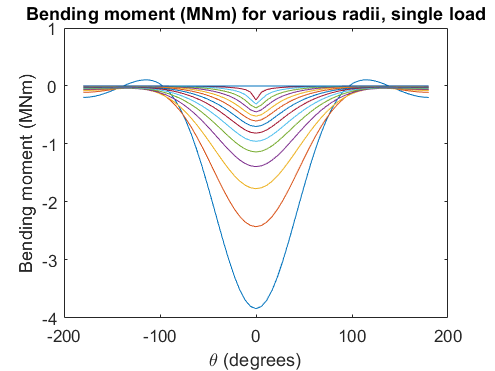

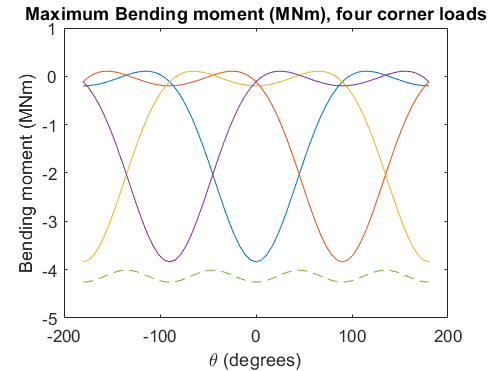

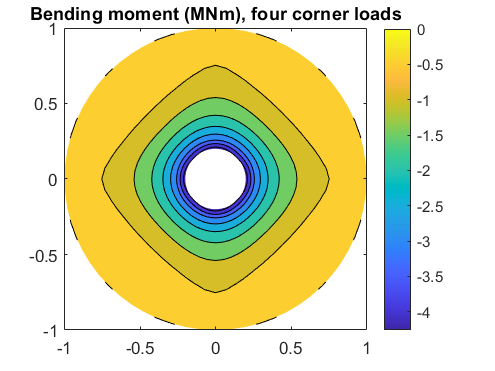

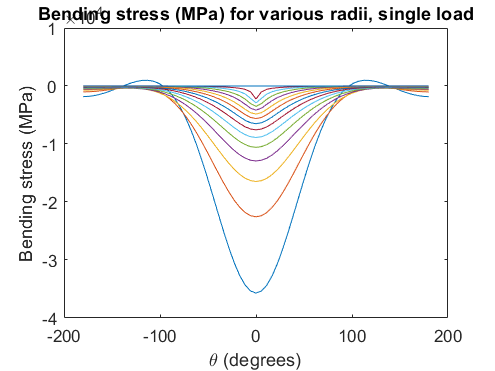

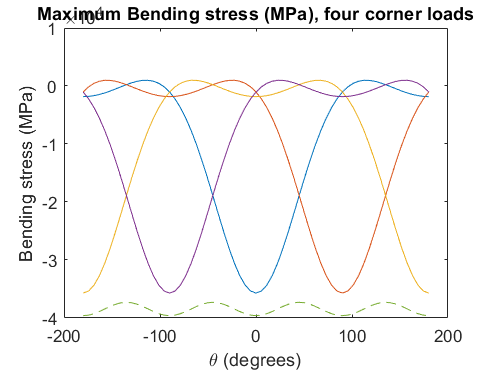

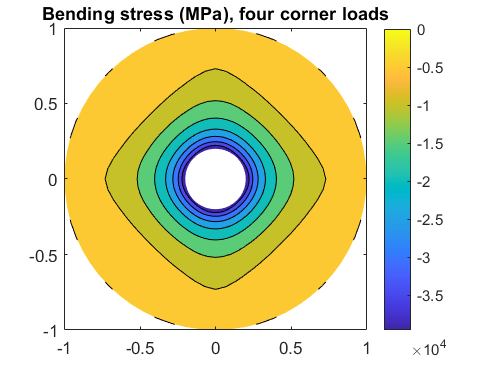

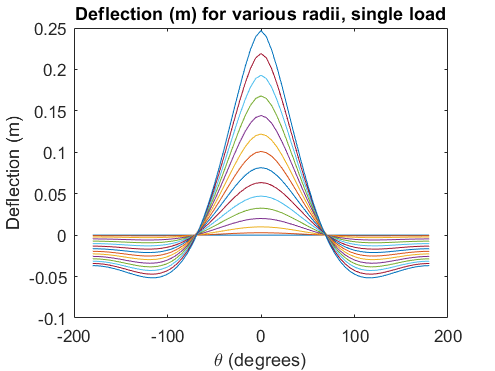

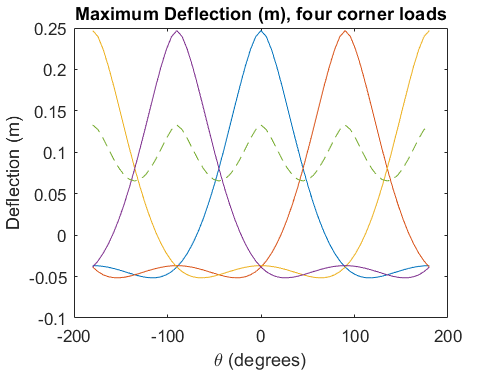

viz_damping_plate()